# Aliasing demo

This LiveScript will demonstrate the effect of aliasing when violating the sampling theorem.

## A signal without aliasing

fs = 44100;                 % sampling frequency
T = 6;                      % duration in seconds
t = 1/fs:1/fs:T;            % vector with samped time points

f_min = 100;                % minimum frequency
f_max = 10000;              % maximum frequency

Now let us generate a signal that changes frequency over time:

sig = chirp(t,f_min,T,f_max,"logarithmic");         % a logarithmic chirp

Cool. Let us play the beast!

sound(.1*sig,fs);           % play back with fs=44100 and reduced amplitude to not blow our ears...

## A signal with aliasing

fs_new = 10000;                                 % sampling frequency
t_new = 1/fs_new:1/fs_new:T;                    % new time vector

sig_new = chirp(t_new,f_min,T,f_max,"logarithmic");     % a chirp - the only difference is the sampling frequency!

Let's play!

sound(.1*sig_new,fs_new);

## WTF?

Let us look at the frequency over time (time-frequency analysis comes in lecture 10):

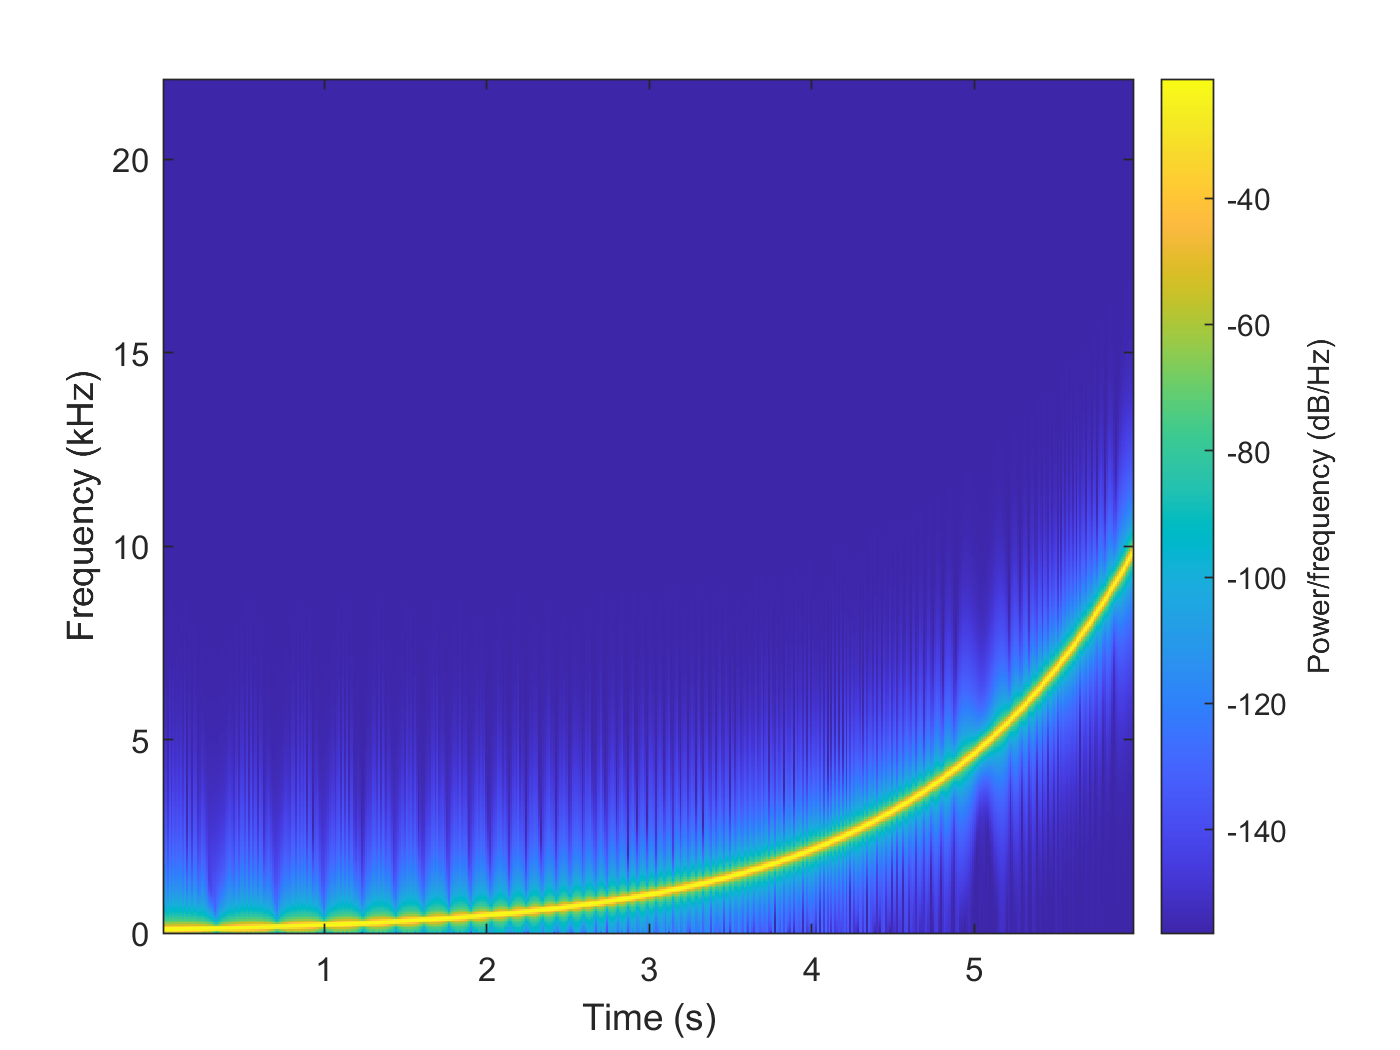

spectrogram(sig,hann(1024),512,[],fs,'yaxis')               % STFT with a 1024pt HANN window and 50% overlap.

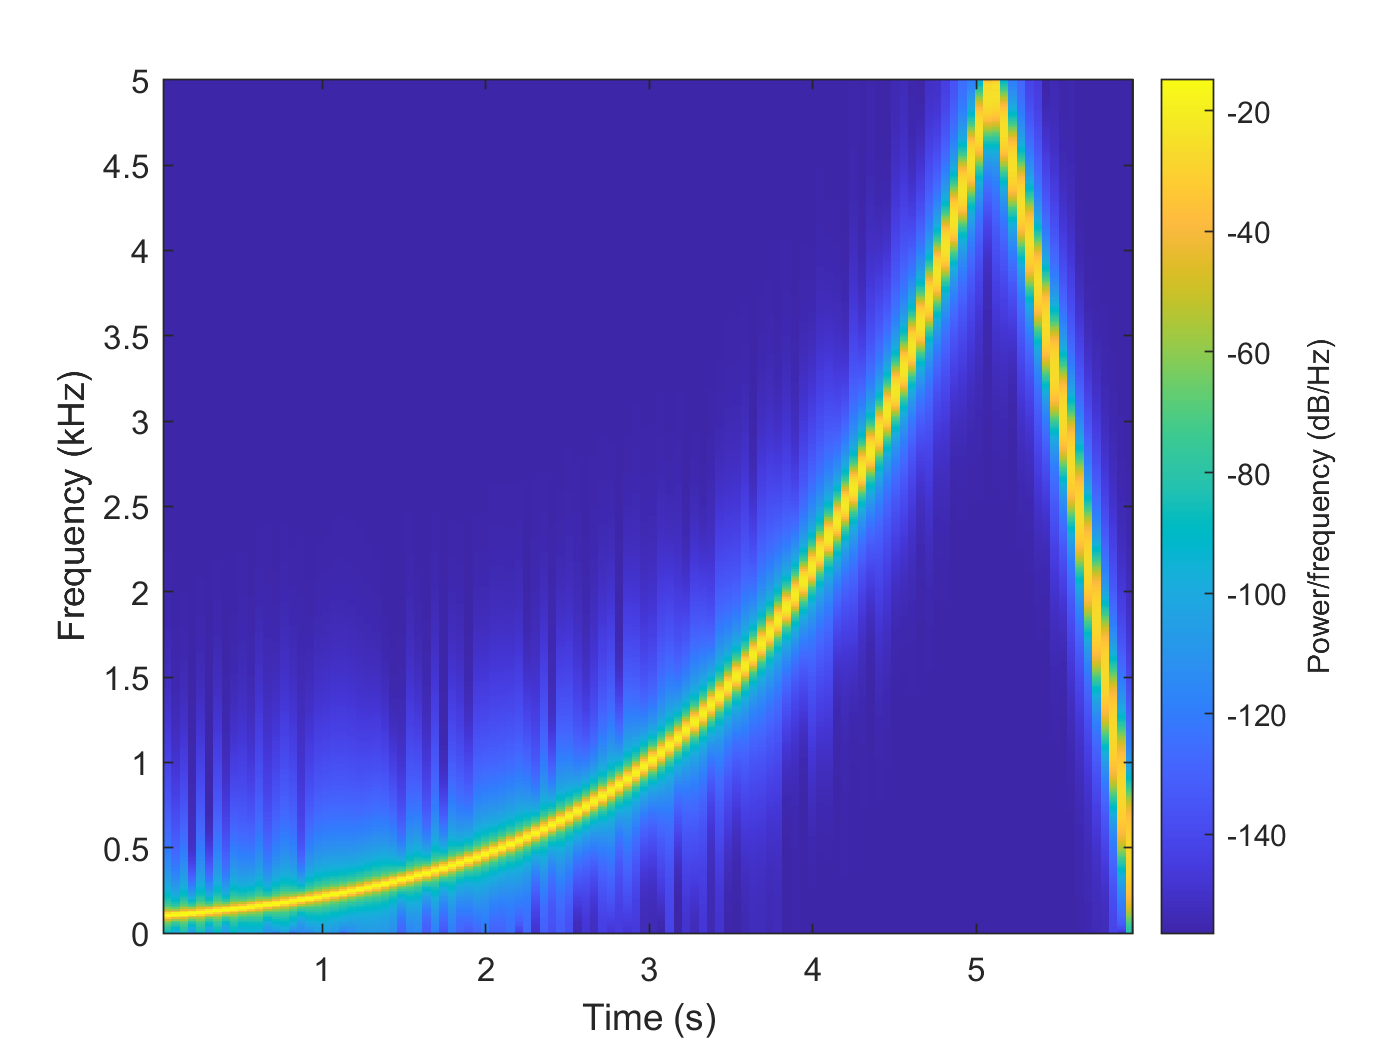

spectrogram(sig_new,hann(1024),512,[],fs_new,'yaxis')       % ... and the frequencies on the y-axis